# **FDS 2024: Field and service robotics**

## `Homework 3 Question 4`

## Andrea Morghen

`Question 5`

Let's import and define some usefull parameter

clc
clear all

load("ws_homework_3_2024.mat");
m=1.5;
g=9.81;
Ib= diag([1.2416 1.2416 2*1.2416]);
Ts=1*10^-3;
e3=[0 0 1]';
time = attitude.time;

These are the parameter for the estimator. The parameter r can be chosen so that the order of the estimator can be changed

C0=100; 
K0=C0;
r=20; 

`Estimator `

q=zeros(6,length(time));
ext_wrench=zeros(6,length(time));
gamma=zeros(6,length(time),r); 


% gamma_r <--> ext_wrench
s=tf('s');
G=K0^r/(s+K0)^r;

c=cell2mat(G.Denominator);
c=c(2:end); % are defined [cr-1 cr-2 ... c0]
%c=flip(c);  % now i have [c0 c1 c2 ....cr-1]

K=zeros(r,1);
P=1; % prod 


for i=1:r
K(i)=c(i)/P;
P=P*K(i);
end

K=flip(K);


for k=1:length(time)-1
    RPY = attitude.signals.values(k,:);
    w = attitude_vel.signals.values(k,:);
    
    
    Q=[1 0 -sin(RPY(2));
        0 cos(RPY(1)) cos(RPY(2))*sin(RPY(1))
        0 -sin(RPY(1)) cos(RPY(1))*cos(RPY(2))];
    
    Q_dot=[0 0 -cos(RPY(2))*w(2);
    0 -sin(RPY(1))*w(1) -sin(RPY(2))*sin(RPY(1))*w(2)+cos(RPY(2))*cos(RPY(1))*w(1);
    0 -cos(RPY(1))*w(1) -sin(RPY(2))*cos(RPY(1))*w(2)-cos(RPY(2))*sin(RPY(1))*w(1)];
    
    S=skew(Q*attitude_vel.signals.values(k,:)');
    
    C=Q'*S*Ib*Q+Q'*Ib*Q_dot;
    
    M=Q'*Ib*Q;
    
    q(:,k+1)=[m*eye(3) zeros(3,3); zeros(3,3) M]*[linear_vel.signals.values(k+1,:)' ; attitude_vel.signals.values(k+1,:)']  ;
    
    Rb=[cos(RPY(2))*cos(RPY(3)) sin(RPY(1))*sin(RPY(2))*cos(RPY(3))-cos(RPY(1))*sin(RPY(3)) cos(RPY(1))*sin(RPY(2))*cos(RPY(3))+sin(RPY(1))*sin(RPY(3));
        cos(RPY(2))*sin(RPY(3)) sin(RPY(1))*sin(RPY(2))*sin(RPY(3))+cos(RPY(1))*cos(RPY(3)) cos(RPY(1))*sin(RPY(2))*sin(RPY(3))-sin(RPY(1))*cos(RPY(3));
    -sin(RPY(2)) sin(RPY(1))*cos(RPY(2)) cos(RPY(1))*cos(RPY(2))];
    gamma(:,k+1,1)=gamma(:,k,1)+K(1)*((q(:,k+1)-q(:,k))-Ts*[m*g*e3-thrust.signals.values(k)*Rb*e3;C'*attitude_vel.signals.values(k,:)'+Q'*tau.signals.values(k,:)']-Ts*ext_wrench(:,k));
    if r>=2
        for i=2:r
            % ki=k0 
           gamma(:,k+1,i)=gamma(:,k,i)+Ts*K(i)*(-ext_wrench(:,k)+gamma(:,k,i-1) );
        end
    end
   ext_wrench(:,k+1)=gamma(:,k+1,r);
end


`Plotting the results`

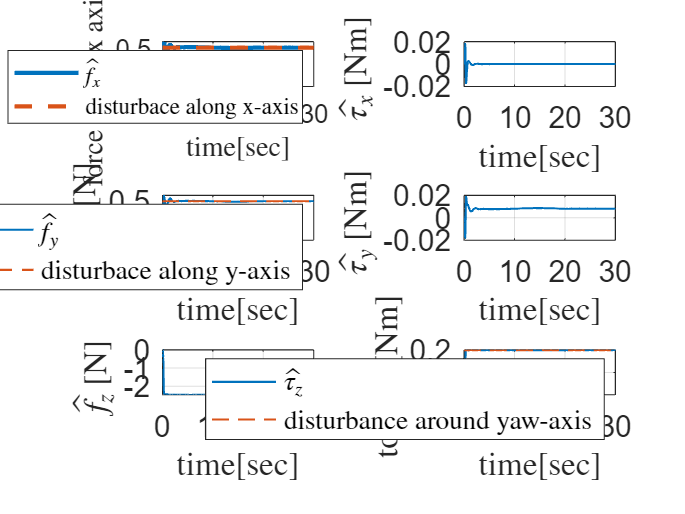

f_ext_x=0.5;
f_ext_y=0.5;
tau_ext_yaw=0.2;

figure()
subplot(3,2,1)
plot(time,ext_wrench(1,:),'lineWidth',2)
xlabel('time[sec]','Interpreter','latex')
ylabel('force along x axis [N]','Interpreter','latex')
grid("on");
hold on
plot(time,f_ext_x.*ones(length(time),1),'LineStyle','--','LineWidth',2)
hold on
legend('$\hat{f_x}$','disturbace along x-axis' ,'Interpreter', 'latex')
set(gca,'Fontsize',12)

subplot(3,2,3)
plot(time,ext_wrench(2,:),'lineWidth',1)
xlabel('time[sec]','Interpreter','latex')
ylabel(' force [N] ','Interpreter','latex')
grid("on");
hold on
plot(time,f_ext_y.*ones(length(time),1),'LineStyle','--','LineWidth',1)
hold on
legend('$\hat{f_y}$','disturbace along y-axis' ,'Interpreter', 'latex')
set(gca,'Fontsize',14)

subplot(3,2,5)
plot(time,ext_wrench(3,:),'lineWidth',1)
xlabel('time[sec]','Interpreter','latex')
ylabel('$\hat{f_z}$ [N] ','Interpreter','latex')
grid("on");
set(gca,'Fontsize',14)


subplot(3,2,2)
plot(time,ext_wrench(4,:),'lineWidth',1)
xlabel('time[sec]','Interpreter','latex')
ylabel('$\hat{\tau_x}$ [Nm] ','Interpreter','latex')
grid("on");
hold on
set(gca,'Fontsize',14)

subplot(3,2,4)
plot(time,ext_wrench(5,:),'lineWidth',1)
xlabel('time[sec]','Interpreter','latex')
ylabel('$\hat{\tau_y}$ [Nm] ','Interpreter','latex')
grid("on");
hold on
set(gca,'Fontsize',14)

subplot(3,2,6)
plot(time,ext_wrench(6,:),'lineWidth',1)
xlabel('time[sec]','Interpreter','latex')
ylabel('torque [Nm] ','Interpreter','latex')
grid("on");
hold on
plot(time,tau_ext_yaw.*ones(length(time),1),'LineStyle','--','LineWidth',1)
hold on
legend('$\hat{\tau_z}$','disturbance around yaw-axis','Interpreter', 'latex')
set(gca,'Fontsize',14)

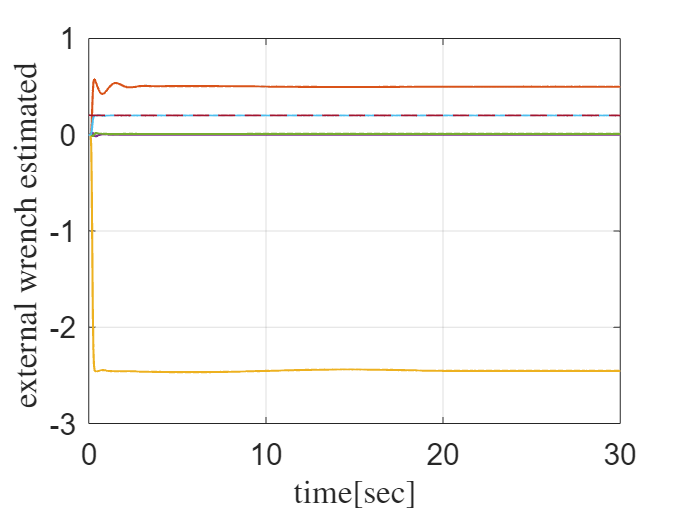



figure()
plot(time,ext_wrench,'lineWidth',1)
xlabel('time[sec]','Interpreter','latex')
ylabel('external wrench estimated ','Interpreter','latex')
grid("on");
hold on
plot(time,tau_ext_yaw.*ones(length(time),1),'LineStyle','--','LineWidth',1)
set(gca,'Fontsize',14)

`compute real mass`


u_tb=thrust.signals.values(end)*Rb*e3;
mass_r_z_1=u_tb(3)/g; % not using disturbance but the steady-state equation

m_tilde= -ext_wrench(3,end)/g;

mass_r_z_2=-m_tilde+m; % computation using the z-disturbance 







